N = 300;          %粒子链总长度
J = 1;          %相互作用强度
wc = 2*J;
tmax = 5;       %模拟时间
Nt = 1000;         %时间采样数
Nc = 80;         %波包初态中心位置
Na = 150;         %散射粒子位置k = pi/2;
delta = 50;      %波包半宽
loop = true;
method = 'eig';


%构建哈密顿量
H0 = zeros(N+1, N+1);
for ii = 1:(N-1)
    H0 = interaction(H0, ii, ii+1, -J);
    H0(ii,ii) = wc;
end
H0(N, N) = wc;
if loop == true
    H0 = interaction(H0, N, 1, -J);
end

%在两端加上轻微的衰减，防止反射
%衰减不能太强，否则会直接反射
for ii = 1:20
    H0(ii,ii) = H0(ii,ii) - 0.1*J*1i;
end
for ii = (N-70):N
    H0(ii,ii) = H0(ii,ii) - 0.05*J*1i;
end


H = H0;
k = pi/4;
Va = -exp(1i*abs(k));
phi_alpha = pi+k;

H = interaction(H, Na-1, N+1,-J);
H = interaction(H, Na, N+1, -J*exp(-1i*phi_alpha));
H(N+1, N+1) = wc + Va;
[VEC, D] = eig(H);
psi0 = [GaussianState(N, Na-80, k, delta);0];
tmax = 100;
tic
[t1, psi1] = psicalc(H, psi0, tmax, 'eig', 200, VEC, D);
toc

历时 1.173144 秒。


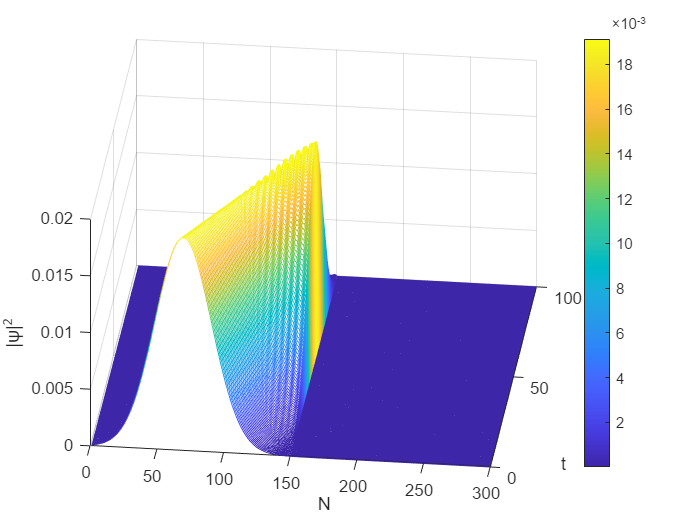

plotpsi(psi1(:,1:N), t1, N)